clear;clc;close all

## Select the Number of Gaussian Mixture Model Components Using PCA

Gaussian mixture models require that you specify a number of components before being fit to data. For many applications, it might be diffcult to know the appropriate number of components. This example shows how to explore the data, and try to get an initial guess at the number of components using principal component analysis.

Load Fisher's iris data set.

load fisheriris;classes = unique(species)

classes = 3×1 cell array
    {'setosa'    }
    {'versicolor'}
    {'virginica' }

The data set contains three classes of iris species. The analysis proceeds as if this is unknown.

Use principal component analysis to reduce the dimension of the data to two dimensions for visualization.

[~,score] = pca(meas,'NumComponents',2);

Fit three Gaussian mixture models to the data by specifying 1, 2, and 3 components. Increase the number of optimization iterations to `1000`. Use dot notation to store the final parameter estimates. By default, the software fits full and different covariances for each component.

GMModels = cell(3,1); % Preallocation
options = statset('MaxIter',1000);rng(1); % For reproducibility
for j = 1:3
    GMModels{j} = fitgmdist(score,j,'Options',options);
    fprintf('\n GM Mean for %i Component(s)\n',j)
    Mu = GMModels{j}.mu
end


 GM Mean for 1 Component(s)


Mu = 	1.0e+-14 *

   -0.2898   -0.0867



 GM Mean for 2 Component(s)


Mu =     1.3212   -0.0954
   -2.6424    0.1909



 GM Mean for 3 Component(s)


Mu =     0.4856   -0.1287
    1.4484   -0.0904
   -2.6424    0.1909


`GMModels` is a cell array containing three, fitted `gmdistribution` models. The means in the three component models are different, suggesting that the model distinguishes among the three iris species.

Plot the scores over the fitted Gaussian mixture model contours. Since the data set includes labels, use `gscatter` to distinguish between the true number of components.

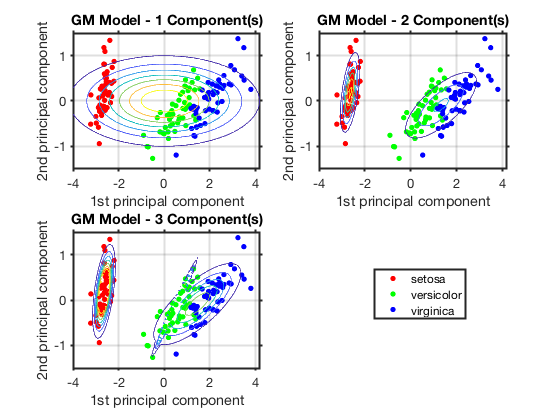

figure
for j = 1:3
    subplot(2,2,j)
    h1 = gscatter(score(:,1),score(:,2),species);h = gca;hold on
    ezcontour(@(x1,x2)pdf(GMModels{j},[x1 x2]),[h.XLim h.YLim],100)
    title(sprintf('GM Model - %i Component(s)',j));
    xlabel('1st principal component');ylabel('2nd principal component');
    if(j ~= 3)
        legend off;
    end
    hold off;grid on
    set(gca,'TickDir','out'); set(gca,'LineWidth',2);set(gca,'FontSize',13);
end
g = legend(h1);g.Position = [0.7 0.25 0.1 0.1];grid on
print('-depsc2','GMMPCAExample.eps');% save to an eps file

The three-component Gaussian mixture model, in conjunction with PCA, looks like it distinguishes between the three iris species.

There are other options you can use to help select the appropriate number of components for a Gaussian mixture model. For example,

- Compare multiple models with varying numbers of components using information criteria, e.g., AIC or BIC.

- Estimate the number of clusters using `evalclusters`, which supports, the Calinski-Harabasz criterion and the gap statistic, or other criteria.